CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])


load('ContourData_S_EE=0.024_7D.mat','ContourData_7D')

## All S_II slices

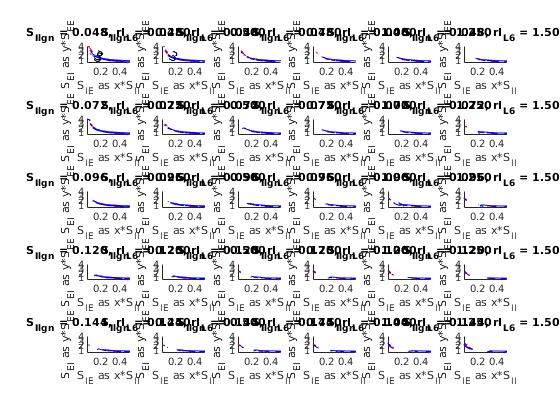

S_EEnow = ContourData_7D.S_EE;
S_IInow = ContourData_7D.S_II;
figure(1)
for S_IlgnInd = 1:ContourData_7D.PanelNum1
    S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
    for rI_L6Ind = 1:ContourData_7D.PanelNum2
        rI_L6now = ContourData_7D.rI_L6test(rI_L6Ind);
        
    subplot(ContourData_7D.PanelNum1, ContourData_7D.PanelNum2, rI_L6Ind+ContourData_7D.PanelNum2*(S_IlgnInd-1))
    hold on
    CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind)); CurrentFrI(CurrentFrI<eps) = nan;
    [C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrE,[3  5 ],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrI,[10 18],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    hold off
    S_Ilgntxt = sprintf('%.3f',S_Ilgnnow);
    rI_L6txt = sprintf('%.3f',rI_L6now);
    title(['S_{Ilgn} = ' S_Ilgntxt ', rI_{L6} = ' rI_L6txt ])
    xlabel('S_{IE} as x*S_{II}');ylabel('S_{EI} as y*S_{EE}')
    %xlim([0.06 0.5])
    end
end

## parameters

sprintf(['S_EE = %.3f, S_II = %.3f, S_Elgn = %.3f, S_amb = %.3f, S_EL6 = %.3f, S_IL6 = %.3f\n',...
         'r_Elgn = %.3f, r_Ilgn = %.3f, r_Eamb = %.3f, r_Iamb = %.3f, r_EL6 = %.3f'],...
         ContourData_7D.S_EE, ContourData_7D.S_II, ContourData_7D.S_Elgn, ContourData_7D.S_amb, ContourData_7D.S_EL6, ContourData_7D.S_IL6,...
         ContourData_7D.lambda_E, ContourData_7D.lambda_I, ContourData_7D.rE_amb, ContourData_7D.rI_amb, ContourData_7D.rE_L6)

ans =     'S_EE = 0.024, S_II = 0.120, S_Elgn = 0.048, S_amb = 0.010, S_EL6 = 0.008, S_IL6 = 0.008
     r_Elgn = 0.080, r_Ilgn = 0.080, r_Eamb = 0.500, r_Iamb = 0.500, r_EL6 = 0.250'


## Check single contourmap

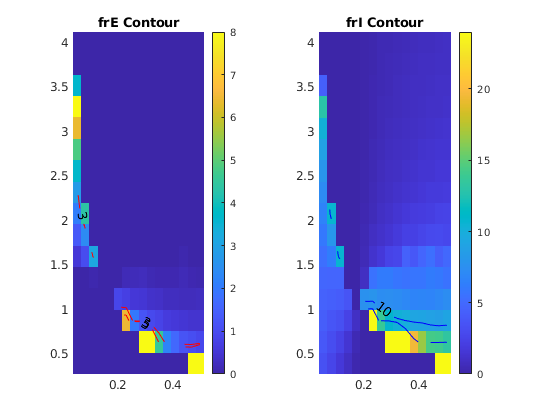

S_IlgnInd = 5; rI_L6Ind = 2;
S_Ilgnnow = ContourData_7D.S_Ilgntest(S_IlgnInd);
rI_L6now = ContourData_7D.rI_L6test(rI_L6Ind);
    CurrentFrE = squeeze(ContourData_7D.Fr_NoFix(1,:,:,S_IlgnInd,rI_L6Ind)); %CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_7D.Fr_NoFix(2,:,:,S_IlgnInd,rI_L6Ind)); %CurrentFrI(CurrentFrI<eps) = nan;
figure('Name','Check Single Contour')
subplot 121
hold on
imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,CurrentFrE)
set(gca,'Ydir','Normal')
CurrentFrE(CurrentFrE<eps) = nan;
[C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrE,[3  5 ],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
hold off
colorbar; caxis([0 8])
title('frE Contour')

subplot 122
hold on
imagesc(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,CurrentFrI)
set(gca,'Ydir','Normal')
CurrentFrI(CurrentFrI<eps) = nan;
[C1,h1]= contour(ContourData_7D.S_IEtest/S_IInow,ContourData_7D.S_EItest/S_EEnow,...
                     CurrentFrI,[10  18 ],'ShowText','on','color','b');
    clabel(C1,h1,'FontSize',10,'Color','k')
hold off
colorbar; caxis([0 24])
title('frI Contour')

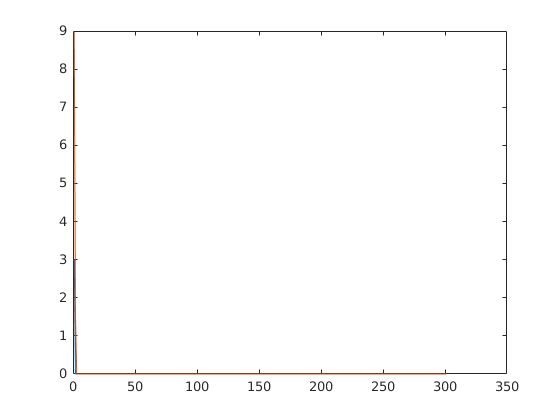

S_IEInd = 3; S_EIInd = 8;
Fr_TrajInterest = ContourData_7D.Fr_NoFixTraj{S_EIInd,S_IEInd,S_IlgnInd,rI_L6Ind};
figure('Name','Traj')
plot(Fr_TrajInterest(1,:))
hold on
plot(Fr_TrajInterest(2,:))

## new test

S_EItest = ContourData_7D.S_EItest;
S_IEtest = ContourData_7D.S_IEtest;

S_EIGridSz = S_EItest(2)-S_EItest(1);
S_IEGridSz = S_IEtest(2)-S_IEtest(1);

[a,b,c,d] = MeanFieldEst_BkGd_Indep_StepSize_ref_testL6(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,...
                                            S_EItest(S_EIInd),...
                                            S_IEtest(S_IEInd)+0*S_IEGridSz...
                                            ,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgntest(S_IlgnInd),rI_amb,...
                                            S_EL6,S_IL6,rE_L6,rI_L6test(rI_L6Ind),...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,StopNum,h,SimuT);